folders = ["4","9","205","411","425"]

folders = 1×5 string array
    "4"    "9"    "205"    "411"    "425"


mean_error = []


mean_error =

     []



std_error = []


std_error =

     []



TRE = []


TRE =

     []



for i=1: length(folders)
    file = 'pt '+folders(i)+'/aruco_marker.bag'

    bag = rosbag(file);
    
    bSel = select(bag,'Topic','/Aruco_Marker')
    % 
    msgStructs = readMessages(bSel,'DataFormat','struct');
    x = cellfun(@(m) double(m.Pose.Position.X),msgStructs);
    y = cellfun(@(m) double(m.Pose.Position.Y),msgStructs);
    z = cellfun(@(m) double(m.Pose.Position.Z),msgStructs);
    aruco_position = [x,y,z]
    mean_aruco_position = mean(aruco_position)
    variance_aruco_position = std(aruco_position)
    file = 'pt '+folders(i)+'/pose_cloud.bag'
    bag = rosbag(file);

    bSel = select(bag,'Topic','/final_pose_output');
    % 
    msgStructs = readMessages(bSel,'DataFormat','struct');
    x = cellfun(@(m) double(m.Poses.Position.X),msgStructs);
    y = cellfun(@(m) double(m.Poses.Position.Y),msgStructs);
    z = cellfun(@(m) double(m.Poses.Position.Z),msgStructs);
    
    position_cloud = [x y z]
    mean_position_cloud = mean(position_cloud)
    var_position_cloud = std(position_cloud)
    if length(aruco_position)>length(position_cloud)
        position_error = position_cloud - aruco_position(1:length(position_cloud),:)
    elseif length(aruco_position)<length(position_cloud)
        position_error = position_cloud(1:length(aruco_position),:) - aruco_position
    end
    %position_error = position_cloud(1:length(aruco_position),:)-aruco_position
    mean_error = [mean_error; mean(position_error)*1000]
    std_error = [std_error; std(position_error)*1000]
    %euclidean_dist = norm(mean_position_cloud -mean_aruco_position)
    
    % Agrima added (computing target registration error (TRE))
    distances = sqrt(sum(position_error.^2, 2));  
    TRE1 = sqrt(mean(distances.^2))
    TRE = [TRE, TRE1];
    
    
end

file = "pt 4/aruco_marker.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\u5579005\Downloads\Warwick_robot_Tests_9.10\pt 4\aruco_marker.bag'
          StartTime: 1.6969e+09
            EndTime: 1.6969e+09
        NumMessages: 61
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [61×4 table]


aruco_position =     0.0754   -0.0023    0.2580
    0.0754   -0.0023    0.2580
    0.0754   -0.0023    0.2580
    0.0754   -0.0023    0.2580
    0.0754   -0.0023    0.2580
    0.0754   -0.0023    0.2580
    0.0754   -0.0023    0.2580
    0.0754   -0.0023    0.2580
    0.0754   -0.0023    0.2580
    0.0754   -0.0023    0.2580


mean_aruco_position =     0.0754   -0.0023    0.2580


variance_aruco_position =      0     0     0


file = "pt 4/pose_cloud.bag"

position_cloud =     0.0754    0.0014    0.2580
    0.0754    0.0009    0.2580
    0.0751    0.0009    0.2580
    0.0756    0.0009    0.2580
    0.0751    0.0006    0.2580
    0.0751    0.0009    0.2580
    0.0759    0.0006    0.2580
    0.0751    0.0009    0.2580
    0.0754    0.0006    0.2580
    0.0754    0.0009    0.2580


mean_position_cloud =     0.0754    0.0008    0.2580


var_position_cloud = 1.0e-03 *

    0.2589    0.2405         0


position_error =    -0.0000    0.0037    0.0000
   -0.0000    0.0031    0.0000
   -0.0003    0.0031    0.0000
    0.0003    0.0031    0.0000
   -0.0003    0.0028    0.0000
   -0.0003    0.0031    0.0000
    0.0006    0.0028    0.0000
   -0.0003    0.0031    0.0000
   -0.0000    0.0028    0.0000
   -0.0000    0.0031    0.0000


mean_error =     0.0600    3.0901    0.0000


std_error =     0.2602    0.2409         0


TRE1 = 0.0031

file = "pt 9/aruco_marker.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\u5579005\Downloads\Warwick_robot_Tests_9.10\pt 9\aruco_marker.bag'
          StartTime: 1.6969e+09
            EndTime: 1.6969e+09
        NumMessages: 1035
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [1035×4 table]


aruco_position =     0.0780   -0.0520    0.2700
    0.0780   -0.0520    0.2700
    0.0780   -0.0520    0.2700
    0.0780   -0.0520    0.2700
    0.0780   -0.0520    0.2700
    0.0780   -0.0520    0.2700
    0.0780   -0.0520    0.2700
    0.0780   -0.0520    0.2700
    0.0780   -0.0520    0.2700
    0.0780   -0.0520    0.2700


mean_aruco_position =     0.0780   -0.0520    0.2700


variance_aruco_position =      0     0     0


file = "pt 9/pose_cloud.bag"

position_cloud =     0.0777   -0.0515    0.2700
    0.0780   -0.0515    0.2700
    0.0774   -0.0517    0.2700
    0.0777   -0.0515    0.2700
    0.0777   -0.0515    0.2700
    0.0777   -0.0515    0.2700
    0.0777   -0.0523    0.2700
    0.0777   -0.0515    0.2700
    0.0777   -0.0515    0.2700
    0.0780   -0.0517    0.2700


mean_position_cloud =     0.0777   -0.0515    0.2700


var_position_cloud = 1.0e-03 *

    0.2146    0.2949    0.0000


position_error =    -0.0003    0.0006   -0.0000
    0.0000    0.0006   -0.0000
   -0.0006    0.0003   -0.0000
   -0.0003    0.0006   -0.0000
   -0.0003    0.0006   -0.0000
   -0.0003    0.0006   -0.0000
   -0.0003   -0.0003   -0.0000
   -0.0003    0.0006   -0.0000
   -0.0003    0.0006   -0.0000
    0.0000    0.0003   -0.0000


mean_error =     0.0600    3.0901    0.0000
   -0.3152    0.5776   -0.0000


std_error =     0.2602    0.2409         0
    0.2146    0.2949         0


TRE1 = 7.5171e-04

file = "pt 205/aruco_marker.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\u5579005\Downloads\Warwick_robot_Tests_9.10\pt 205\aruco_marker.bag'
          StartTime: 1.6969e+09
            EndTime: 1.6969e+09
        NumMessages: 533
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [533×4 table]


aruco_position =     0.0412    0.0022    0.2830
    0.0412    0.0022    0.2830
    0.0412    0.0022    0.2830
    0.0412    0.0022    0.2830
    0.0412    0.0022    0.2830
    0.0412    0.0022    0.2830
    0.0412    0.0022    0.2830
    0.0412    0.0022    0.2830
    0.0412    0.0022    0.2830
    0.0412    0.0022    0.2830


mean_aruco_position =     0.0412    0.0022    0.2830


variance_aruco_position =      0     0     0


file = "pt 205/pose_cloud.bag"

position_cloud =     0.0406    0.0016    0.2830
    0.0412    0.0022    0.2830
    0.0412    0.0019    0.2830
    0.0412    0.0022    0.2830
    0.0409    0.0022    0.2830
    0.0409    0.0016    0.2830
    0.0409    0.0019    0.2830
    0.0409    0.0019    0.2830
    0.0409    0.0022    0.2830
    0.0409    0.0019    0.2830


mean_position_cloud =     0.0411    0.0020    0.2830


var_position_cloud = 1.0e-03 *

    0.2546    0.2795    0.0000


position_error =    -0.0006   -0.0006    0.0000
    0.0000    0.0000    0.0000
    0.0000   -0.0003    0.0000
    0.0000    0.0000    0.0000
   -0.0003    0.0000    0.0000
   -0.0003   -0.0006    0.0000
   -0.0003   -0.0003    0.0000
   -0.0003   -0.0003    0.0000
   -0.0003    0.0000    0.0000
   -0.0003   -0.0003    0.0000


mean_error =     0.0600    3.0901    0.0000
   -0.3152    0.5776   -0.0000
   -0.1485   -0.2028    0.0000


std_error =     0.2602    0.2409         0
    0.2146    0.2949         0
    0.2546    0.2795         0


TRE1 = 4.5277e-04

file = "pt 411/aruco_marker.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\u5579005\Downloads\Warwick_robot_Tests_9.10\pt 411\aruco_marker.bag'
          StartTime: 1.6969e+09
            EndTime: 1.6969e+09
        NumMessages: 6
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [6×4 table]


aruco_position =     0.1218    0.0050    0.2820
    0.1218    0.0050    0.2820
    0.1218    0.0050    0.2820
    0.1218    0.0050    0.2820
    0.1218    0.0050    0.2820
    0.1218    0.0050    0.2820


mean_aruco_position =     0.1218    0.0050    0.2820


variance_aruco_position =      0     0     0


file = "pt 411/pose_cloud.bag"

position_cloud =     0.1221    0.0059    0.2820
    0.1232    0.0050    0.2830
    0.1239    0.0050    0.2840
    0.1221    0.0056    0.2820
    0.1229    0.0056    0.2830
    0.1229    0.0053    0.2830
    0.1232    0.0050    0.2830
    0.1229    0.0050    0.2830
    0.1229    0.0050    0.2830
    0.1229    0.0047    0.2830


mean_position_cloud =     0.1229    0.0054    0.2829


var_position_cloud = 1.0e-03 *

    0.5817    0.3335    0.6018


position_error =     0.0003    0.0009   -0.0000
    0.0014    0.0000    0.0010
    0.0021    0.0000    0.0020
    0.0003    0.0006   -0.0000
    0.0011    0.0006    0.0010
    0.0011    0.0003    0.0010


mean_error =     0.0600    3.0901    0.0000
   -0.3152    0.5776   -0.0000
   -0.1485   -0.2028    0.0000
    1.0354    0.4283    0.8333


std_error =     0.2602    0.2409         0
    0.2146    0.2949         0
    0.2546    0.2795         0
    0.6844    0.3662    0.7528


TRE1 = 0.0017

file = "pt 425/aruco_marker.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\u5579005\Downloads\Warwick_robot_Tests_9.10\pt 425\aruco_marker.bag'
          StartTime: 1.6969e+09
            EndTime: 1.6969e+09
        NumMessages: 420
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [420×4 table]


aruco_position =     0.1130    0.0012    0.2780
    0.1130    0.0012    0.2780
    0.1130    0.0012    0.2780
    0.1130    0.0012    0.2780
    0.1130    0.0012    0.2780
    0.1130    0.0012    0.2780
    0.1130    0.0012    0.2780
    0.1130    0.0012    0.2780
    0.1130    0.0012    0.2780
    0.1130    0.0012    0.2780


mean_aruco_position =     0.1130    0.0012    0.2780


variance_aruco_position =      0     0     0


file = "pt 425/pose_cloud.bag"

position_cloud =     0.1134    0.0018    0.2780
    0.1137    0.0022    0.2780
    0.1134    0.0028    0.2780
    0.1137    0.0022    0.2780
    0.1134    0.0022    0.2780
    0.1134    0.0022    0.2780
    0.1130    0.0018    0.2780
    0.1134    0.0018    0.2780
    0.1137    0.0024    0.2780
    0.1124    0.0028    0.2780


mean_position_cloud =     0.1134    0.0021    0.2780


var_position_cloud = 1.0e-03 *

    0.3648    0.2570    0.0000


position_error =     0.0003    0.0006    0.0000
    0.0006    0.0009    0.0000
    0.0003    0.0015    0.0000
    0.0006    0.0009    0.0000
    0.0003    0.0009    0.0000
    0.0003    0.0009    0.0000
   -0.0000    0.0006    0.0000
    0.0003    0.0006    0.0000
    0.0006    0.0012    0.0000
   -0.0006    0.0015    0.0000


mean_error =     0.0600    3.0901    0.0000
   -0.3152    0.5776   -0.0000
   -0.1485   -0.2028    0.0000
    1.0354    0.4283    0.8333
    0.3696    0.9147    0.0000


std_error =     0.2602    0.2409         0
    0.2146    0.2949         0
    0.2546    0.2795         0
    0.6844    0.3662    0.7528
    0.3648    0.2570         0


TRE1 = 0.0011

b = bar(mean_error,'grouped')

b =   1×3 Bar array:

    Bar    Bar    Bar


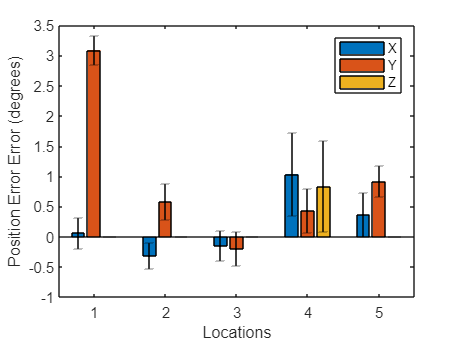

%b = bar(error_orientations_all_tests)
hold on
xlabel("Locations")

ylabel("Position Error Error (degrees)")

%xlabels = categorical({'x 118', 'y 118', 'z 118';'x 280', 'y 280', 'z 280';'x 332', 'y 332', 'z 332' ;'x 333', 'y 333', 'z 333'});
[ngroups,nbars] = size(mean_error);
% Get the x coordinate of the bars
v = nan(nbars, ngroups);
for i = 1:nbars
    v(i,:) = b(i).XEndPoints;
end
% Plot the errorbars
errorbar(v',mean_error,std_error,'k','linestyle','none');
hold off
legend(["X","Y","Z"])

## Agrima added: TRE plot


b = bar(TRE,'grouped')

b =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: [0 0.4470 0.7410]
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [1 2 3 4 5]
        YData: [0.0031 7.5171e-04 4.5277e-04 0.0017 0.0011]

  Show all properties


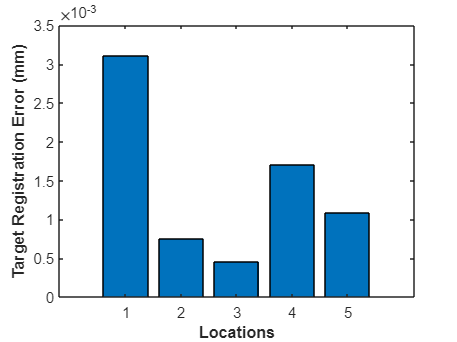

hold on
xlabel("Locations", 'FontWeight', 'bold')
ylabel("Target Registration Error (mm)", 'FontWeight', 'bold')

[ngroups,nbars] = size(TRE);
v = nan(nbars, ngroups);
for i = 1:nbars
    v(i,:) = b(i).XEndPoints;
end

Unable to perform assignment because the size of the left side is 1-by-1 and the size of the right side is 1-by-5.

hold off

